ans = 2

min_lambda = 1

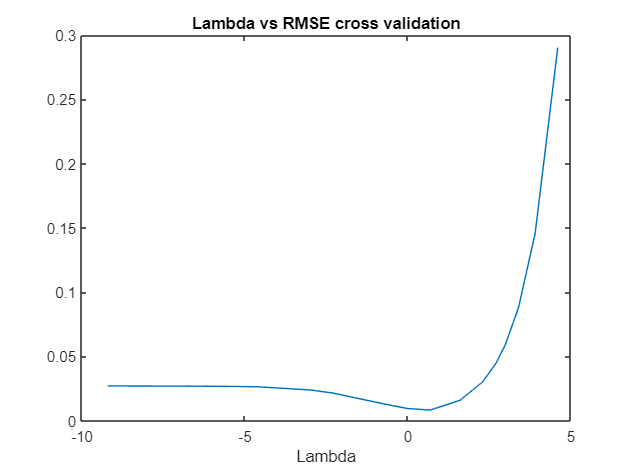

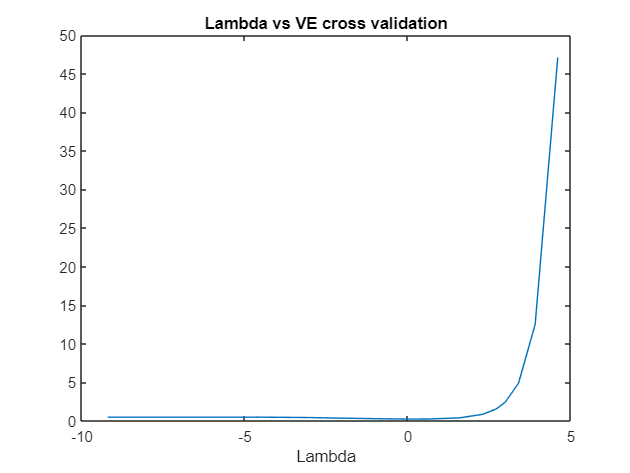

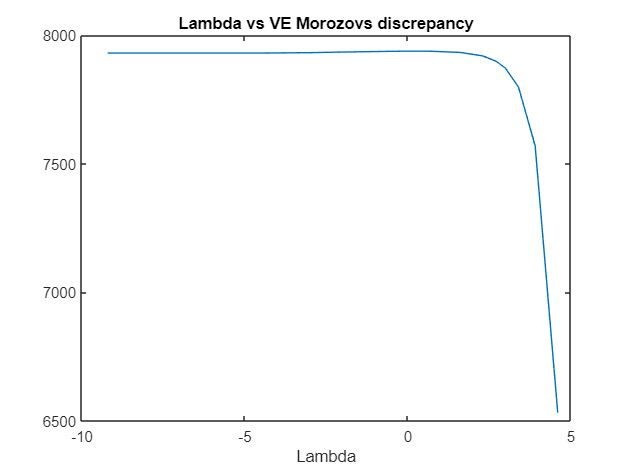

ans = 1

min_lambda = 0.5000

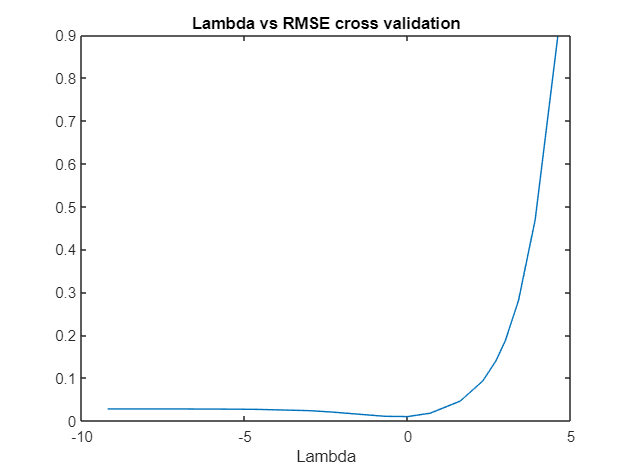

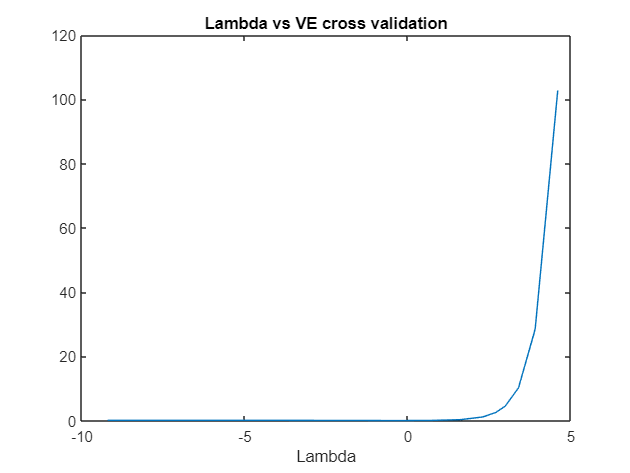

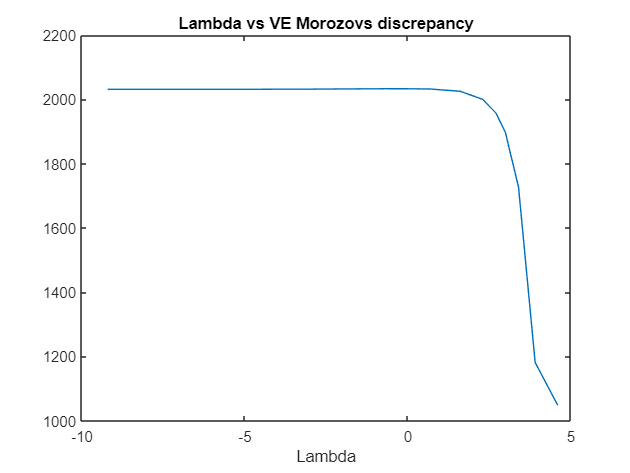

ans = 2

min_lambda = 2

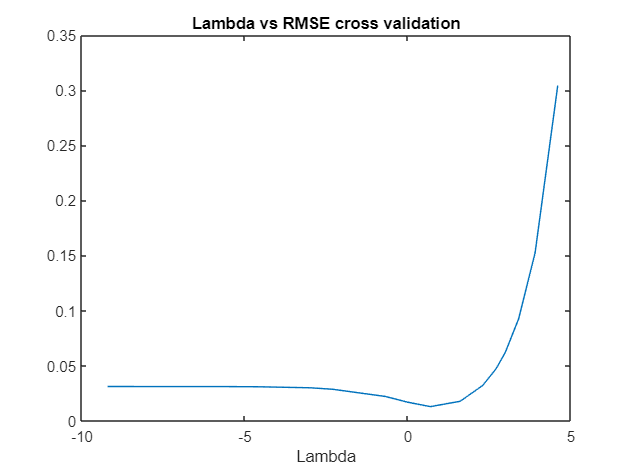

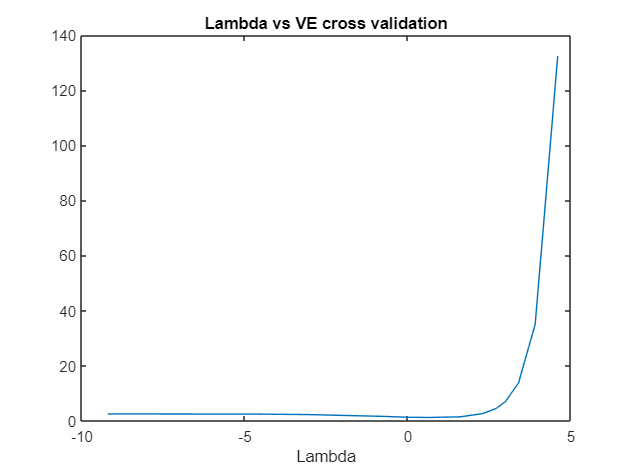

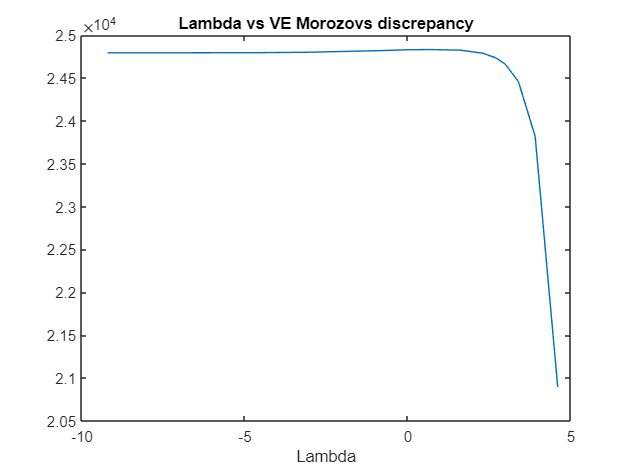

ans = 10

min_lambda = 10

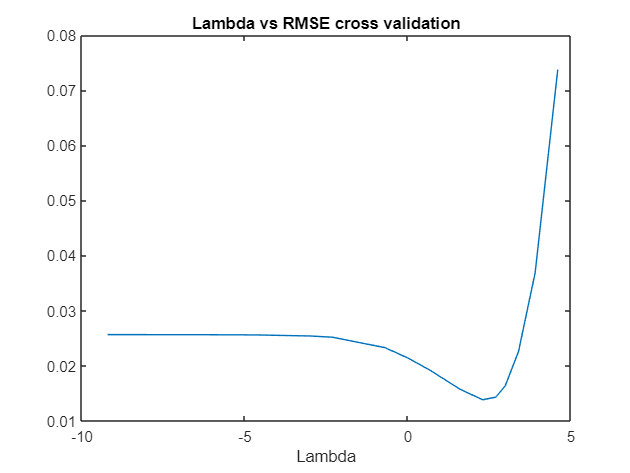

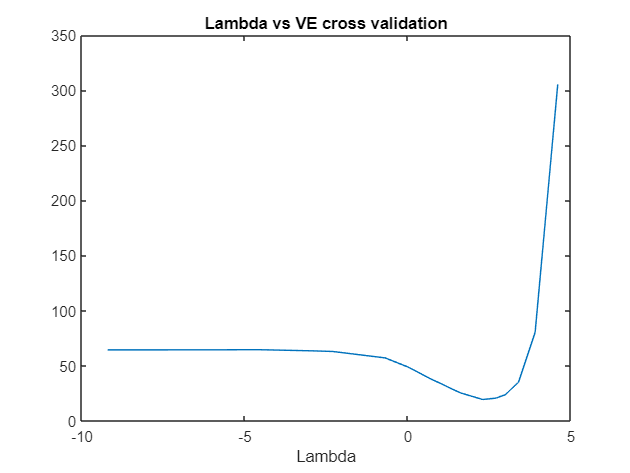

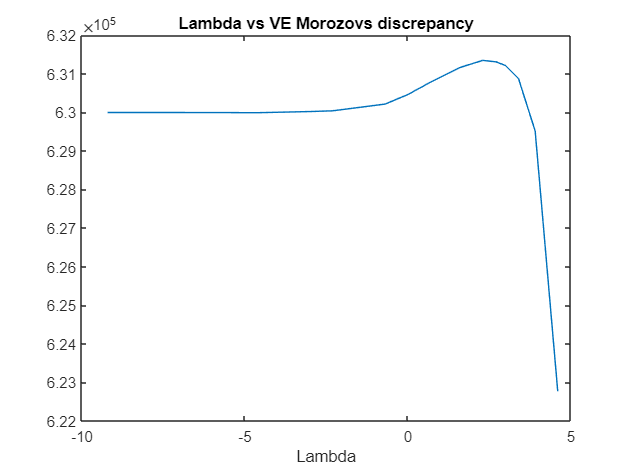

DCT = dctmtx(500);
Phi = ((rand(300,500)<0.5)-0.5)*2*(1/sqrt(300));

lam = [0.0001, 0.0005, 0.001, 0.005, 0.01, 0.05, 0.1, 0.5, 1, 2, 5, 10, 15, 20, 30, 50, 100];
suppt = [5, 10, 15, 20];
A1 = Phi(1:270,:)*DCT;
A2 = Phi(271:300,:);
alpha = eigs(A1'*A1,1);
for i=1:4
    theta = zeros(500,1);
    perm = randperm(500,suppt(i));
    for q=1:suppt(i)
        theta(perm) = rand*1000;
    end
    x = DCT*theta;
    sig = (0.025/300)*sum((abs(Phi*x)),'all');
    y = Phi*x+ normrnd(0, sig,300,1);
    R = y(1:270,:);
    V = y(271:300,:);
    min_val_err = 100000;
    min_lambda = -1;
    min_err1 = 100000;
    min_lambda1 = -1;
    RMSE = double(zeros(1,17));
    VE = double(zeros(1,17));
    RMSE1 = double(zeros(1,17));
    VE1 = double(zeros(1,17));
    for j = 1:17
        
        lambda = lam(j);
        cvx_begin
            cvx_quiet(true);
            variable theta_rec(500,1);
            minimize(sum_square(R-A1*theta_rec)+lambda*(norm(theta_rec,1)));
        cvx_end
        theta_recon = theta_rec;
        x_g = DCT*theta_recon;
        rmse = norm(x-x_g,2)/norm(x,2);
        RMSE(j) = rmse;
        ve = sum((V-A2*x_g).^2,'all')/30;
        VE(j) = ve;
        VE1(j) = abs(ve*30-m*sig*sig);
        if ve<min_val_err || j==1
            min_val_err = ve;
            min_lambda = lam(j);
        end
        if abs(ve*30-m*sig*sig)<min_err1 || j==1
            min_err1 = abs(ve*30-m*sig*sig);
            min_lambda1 = lam(j);
        end
    end
    [mval,armin] = min(RMSE);
    lam(armin)
    min_lambda
    plot(log(lam),RMSE);
    title('Lambda vs RMSE cross validation');
    xlabel("Lambda");
    figure;
    plot(log(lam),VE);
    title('Lambda vs VE cross validation');
    xlabel("Lambda");
    figure;
    plot(log(lam),VE1);
    title('Lambda vs VE Morozovs discrepancy');
    xlabel("Lambda");
    figure;
end